# Computer Assignment 1 - Part 2: Numerical Integration 

## Task 2: 

Select a function that can be easily integrated to compare its approximation from the Composite Midpoint method with the exact value. Then, select an interval [a, b] to integrate the function over, as well as a sequence of increasing N. 

Compute the approximation of the integral of function f over interval [a, b] for each value of N. 

f = @(x) sin(x);  
a = 0; b = 1;   % limits of integration
N = 100;        % number of points in the partition of [a,b]
% Composite Midpoint Rule
compositeMidpoint(f,a,b,N)

ans = 0.4597

## Absolute Error

Now find the absolute error for each value of N.

N_vec= 2.^(2:15);                        % N = 2^2, 2^3, ..., 2^15
err_vec_midpoint = zeros(size(N_vec));   % create a vector to store composite midpoint rule error for each N 

for i = 1:length(N_vec)
    N = N_vec(i);
    err = abs(compositeMidpoint(f, a, b, N) - (1-cos(1)))    % abs err = approx - exact
    err_vec_midpoint(i) = err;                               % store the error in err_vec_midpoint vector   
end

err = 0.0021

err = 3.9113e-04

err = 8.5140e-05

err = 1.9932e-05

err = 4.8260e-06

err = 1.1876e-06

err = 2.9456e-07

err = 7.3353e-08

err = 1.8302e-08

err = 4.5711e-09

err = 1.1422e-09

err = 2.8549e-10

err = 7.1363e-11

err = 1.7841e-11

As N is repeatedly doubled, the approximation error decreases by roughly a factor of 4.  

## Error Behavior

We can check the decreasing factor by performing element-wise division: 

err_vec_midpoint(1:end-1)'./err_vec_midpoint(2:end)' % element-wise division

ans =     5.4589
    4.5940
    4.2715
    4.1302
    4.0638
    4.0316
    4.0157
    4.0078
    4.0039
    4.0020


The difference factor produced by the element-wise division approaches a value of 4, which confirms that as N gets larger, the approximation error decreases by about a factor of 4. To find $\alpha$, take the square root of the approximate common difference factor (4) to find that $\alpha =2$. Therefore, the composite midpoint rule is second order accurate.  

From Math 4700, the principal error term of the Compostie Midpoint Rule is $$\frac{h^3}{24}f''(\xi)$$ for some $\xi \in[a,b]$ and $h=\frac{b-a}{N-1}$. 

We say the Composite Midpoint Rule is $O(h^2)$ (second order accurate) and its error is proportional to $h^2 = \Big( \frac{b-a}{N-1}\Big)^2$. When $N$ is large, $\frac{1}{N^2}\approx\frac{1}{(N-1)^2}$. This confirms our finding of $\alpha =2$ from a general perspective. 

## Convergence plot

The plot below confirms the value of $\alpha$ obtained above with a convergence plot of the number of points N against the absolute error (green). A line with slope 2 has been plotted alongside the covergence plot to verify the value of $\alpha$ (black). Since the green and black lines are parallel, this confirms our value of $\alpha$ from a graphical perspective.

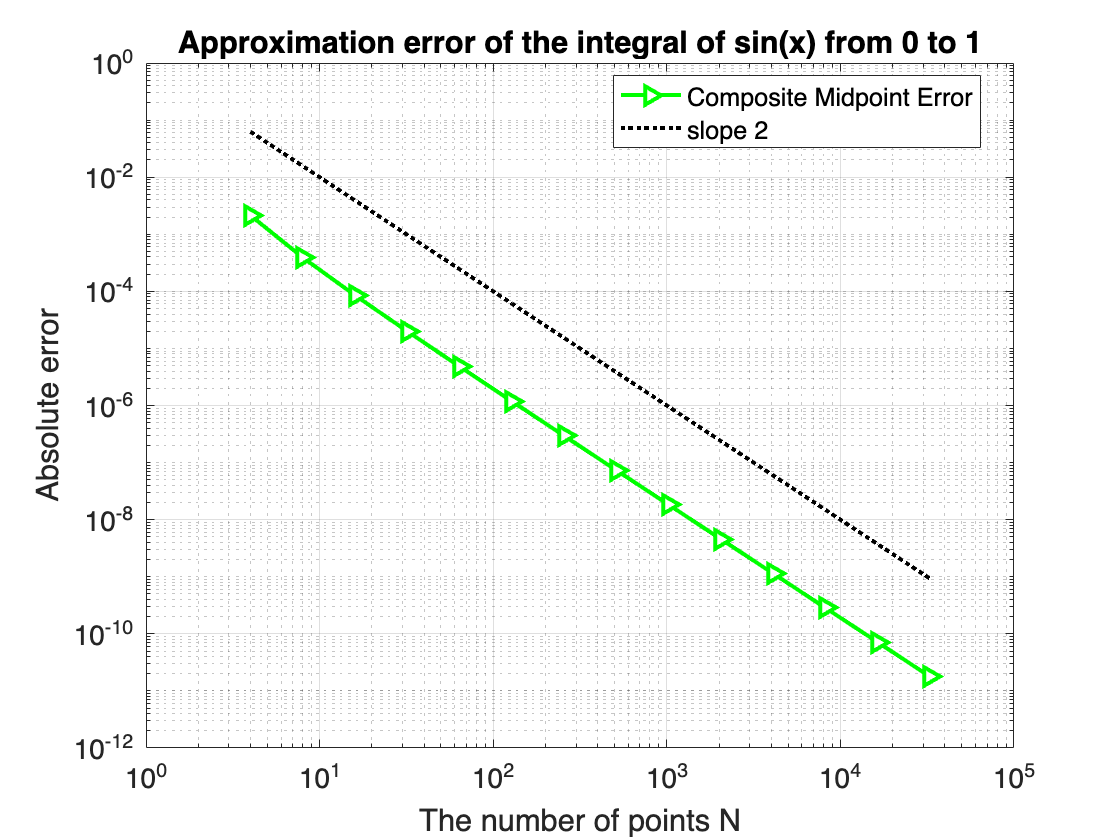

figure
loglog(N_vec, err_vec_midpoint, 'g>-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'w')
hold on
loglog(N_vec, 1./(N_vec.^2), 'k:', 'LineWidth', 2)

hold off
grid on

xlabel('The number of points N');
ylabel('Absolute error');
legend('Composite Midpoint Error','slope 2','location','best');
title('Approximation error of the integral of sin(x) from 0 to 1');
set(gca,'fontsize',14); % set axis font size

## Composite Midpoint Function

function result = compositeMidpoint(f, a, b, N) 
% f: function handle
% a, b: lower & upper 
% N: total number of nodes

x = linspace(a, b, N); % divides interval [a,b] into equal partitions w/ N nodes
h = (b-a)/(N-1); % compute the width of each interval 
midpoints = (x(1:N-1) + x(2:N))/2; % calculate midpoint at each subinterval
f_values = f(midpoints); % evaluates at each midpoint

result = h .* sum(f_values);

end